## **Data Collection and Preparation**

% clear; clc; format shortG;
% % Dealing with missing data
% [Lag_max, ~]= Cross_correlation ('Water_level.csv','Upstream.csv',30);
% [Water_Level_1,~,~]= Data_imputation('Water_level.csv','Upstream.csv',abs(Lag_max));
% 
% [Lag_max,~]= Cross_correlation ('R2.csv', 'R1.csv',30);
% [rainfall_1,~,~]= Data_imputation('R2.csv', 'R1.csv' ,abs(Lag_max));
% 
% % Prepared data     
% Ref_table = innerjoin (Water_Level_1,rainfall_1,'Keys','Time');
% 
% W1 = table2array(Ref_table(:,2)) .*1000; % All values in mm
% R1 = table2array(Ref_table(:,3));
% 
% ref_in = [W1 R1];
% writematrix(ref_in,'Ref_ini.csv');

## **Model Development - All data by Nonlinear AutoRegressive eXogenous method**

% ref_in = readmatrix("Ref_ini.csv");
% W1 = ref_in (:,1);
% R1 = ref_in (:,2);
% 
% % Cross correlation to find first guess of feedback delay
% % [c,lags] = xcorr(W1,R1,'coeff'); 
% % [~, idx] = max(c);
% % Lag_max1= lags(1,idx);
% %--------------------------- Classification of data for event identification ----------------------------------------------------------------
% Full_Capacity = 0.85 * 1000;         % Full_Capacity is the maximum capacity of UDS (mm)
% state_Performance = 1; % make sample rather than make event
% change_Factor = 2; % Percentage of delta changes in which events are finished
% remove_Factor = 6; % Removing below 7 point based on time lag
% Delay_factor = 1; % Time step neglected between rainfall
% 
% [idx_Event_F] = Event_Identification (W1,R1,Delay_factor,state_Performance,change_Factor,remove_Factor,change_Factor,change_Factor,Full_Capacity);
% olo = 1;
% aris=0;
% for i=1:numel(idx_Event_F(1,:))
%     if nnz(idx_Event_F(:,i))<7
%        aris (olo,1) = i;
%        olo = olo+1;
%     end  
% end
% idx_Event_F(:,aris) = [];
% writematrix(idx_Event_F,'Events.csv');

clear; clc; format shortG;
ref_in = readmatrix("Ref_ini.csv");
idx_Event_F = readmatrix('Events.csv');
% ------------------------------- Optimisation -----------------------------------

%---------------------- Initial data: Data which can be optimised ---------------------

% One layer and 3 layers are tested before
Hidden_layer = [10 10];                 % Number of nodes in each layer

% Longest time step can be teseted
Num_St_Ah = [1 4 8 12];           % Steps ahead

Num_St_Ah =     12


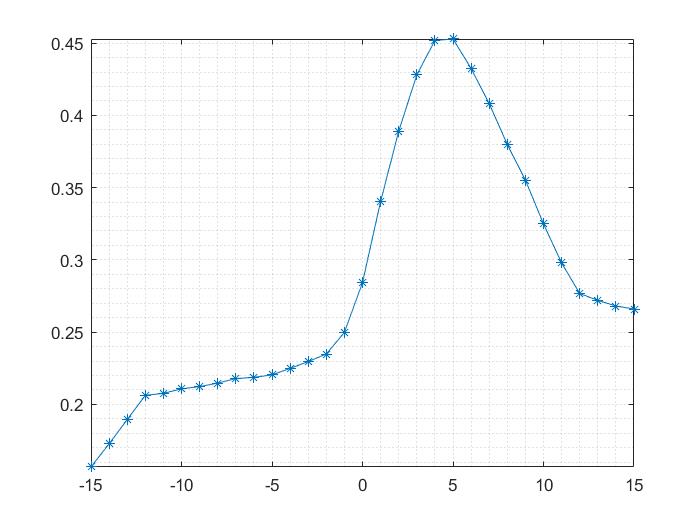


% Now 15% of entire data is used for testing
Train_ratio = 78/100;             % Training data proportion
Val_ratio   = 22/100;             % Validation data proportion
Test_ratio  = 0/100;             % Test data proportion
ratio_t = [Train_ratio Val_ratio Test_ratio];

% We have no any regulation to specify the maximum failure of stopping model
Max_fail = 5;
% Based on papers
Counter_seed = 1;                 % Number of trials in each time step      

%------------------- Runnig model --------------------------
% [c,lags] = xcorr(ref_in(:,1),ref_in(:,2), 15,'coeff');
% C(:,1)=c(:,1);


idx_Event_F1 = idx_Event_F (:,1: end-163); % for training
idx_Event_F2 = idx_Event_F (:,end-162:end); % for testing
Counter_Step = 0;
mm = 0;
l=0;
% for kk=[1 3  5   8 10 15 20 25 30 35 40]
%    l=l+1; 
for i = Num_St_Ah
    Counter_Step = Counter_Step+1;
    FeedB_delay_O = kk;     % Y
    FeedB_delay_I1 = kk;   % X1      
    FeedB_delay_I = [FeedB_delay_I1;FeedB_delay_O];

    for j = 1:Counter_seed
        Y_simo = [];
        X_simo = [];
        Timeo = [];
        Data_tto = [];
        Addet_matto = [];
        [~, Y_simo,X_simo,~,Timeo,Data_tto,Addet_matto,c,lags]= NARX_modified (FeedB_delay_I,Hidden_layer,i,ratio_t,Max_fail,1, ref_in,idx_Event_F1,idx_Event_F2);
        CounterL=j+((Counter_Step-1)*Counter_seed);
%     C(:,l)=c(:,1);
% end
% end
% end

   ----------------- Performance assessment ---------
        P_RMSE_R (CounterL,1) = sqrt (sum((X_simo-Y_simo).^2)/numel(X_simo));
    
        E = X_simo - Y_simo;
        SSE = sum(E.^2);
        U = X_simo - mean(X_simo);
        SSU = sum(U.^2);
        NSout_R (CounterL,1) = 1/(2-(1 - SSE/SSU));
        
        X_sim = X_simo (Addet_matto);
        Y_sim = Y_simo (Addet_matto);
        
        Data_ttor = Data_tto (2,:);
        Data_ttor = Data_ttor (Addet_matto);
        
        P_RMSE_E (CounterL,1) = sqrt (sum((X_sim-Y_sim).^2)/numel(X_sim));
    
        E = X_sim - Y_sim;
        SSE = sum(E.^2);
        U = X_sim - mean(X_sim);
        SSU = sum(U.^2);
        NSout_E (CounterL,1) = 1/(2-(1 - SSE/SSU));
        
        Timet (CounterL,1) = Timeo;
        mm=mm+1
        sim_raw = array2table ([Data_tto(2,:) ;X_simo ;Y_simo]')  ;      
        sim_event = array2table ([Data_ttor ;X_sim ;Y_sim]') ;  
        writetable(sim_raw,'Dataresult_R.xls','sheet',mm);
        writetable(sim_event,'Dataresult_E.xls','sheet',mm);
    end    
end
end

Per_t1_R=array2table ([P_RMSE_R NSout_R Timet]);
Per_t1_R.Properties.VariableNames = {'RSME' 'NNSE' 'Time' };
Per_t1_E=array2table ([P_RMSE_E NSout_E Timet ] );
Per_t1_E.Properties.VariableNames = {'RSME' 'NNSE' 'Time' };

writetable(Per_t1_R,"Result.xls",'sheet','Perraw','WriteVariableNames',true);
writetable(Per_t1_E,"Result.xls",'sheet','Perhyb','WriteVariableNames',true);

## **Visualisation**

% % clearvars('-except','PointR1','PointR2','PointR3','Iter','Time','X_sim','Y_sim','Num_St_Ah','Counter_seed', 'Full_Capacity',...
%     
% Y_sim_plot_t = zeros(numel(Num_St_Ah),numel(Y_sim(1,:)));
% for i=1:numel(Num_St_Ah(1,:))
%      Y_next = zeros (1, numel(Y_sim(1,:)));
%      for j=1: Counter_seed
%          Y_sim_plot_t(i,:)= Y_next(1,:) + Y_sim ((i-1)*Counter_seed+j,:);
%          Y_next(1,:) = Y_sim_plot_t(i,:);
%      end
%      Y_sim_plot_t(i,:)=Y_sim_plot_t(i,:) ./ Counter_seed;
% end
% 
% A_1=['NARX '  num2str(15)  '-Minute ahead'];
% A_2=['NARX '  num2str(60)  '-Minute ahead'];
% A_3=['NARX '  num2str(120)  '-Minute ahead'];
% A_4=['NARX '  num2str(180)  '-Minute ahead'];
% C={'Measurement','Full capacity', A_1, A_2,A_3,A_4};
% NO = 1:numel (X_sim(1,:));
% plot (NO,X_sim(1,:),'color','r');
% hold on
% F_capasity= X_sim(1,:);
% F_capasity (1,:)= Full_Capacity;
% plot(NO,F_capasity,'color','k')
% 
% for i=1: numel(Num_St_Ah(1,:))
%     plot (NO,Y_sim_plot_t(i,:));
% end
% legend (C(1:i+2),'Location',"best");
% title ('Comparison between measurement and NARX predictions');
% xlabel('Time Step (15 minutes)');
% ylabel('Water Depth (mm)');
% grid minor
% axis tight
% ylim ([100 inf])
% hold off